Q2)

% import msoa data and trip counts
data = readtable('UK_census_msoa_stats.csv')

data = 7201×10 table
      MSOACode                 MSOAName               Longitude    Latitude    Population    Area    Households    TownsendDeprivationScore    O_trips_     D_trips_ 
    _____________    _____________________________    _________    ________    __________    ____    __________    ________________________    ________    __________

    {'E02000001'}    {'City of London 001E'      }    -0.095723     51.515        7375       290        4385                3.9315               7580      7.1305e+05
    {'E02000002'}    {'Barking and Dagenham 001A'}      0.13556     51.585        6775       216        2713                4.3451               3938            1248
    {'E02000003'}    {'Barking and Dagenham 002F'}       0.1391     51.572       10045       214        3834                2.4328               7386            5604
    {'E02000004'}    {'Barking and Dagenham 003A'}      0.17463      51.56        6182       249        2318               0.92629               471

a)

Testing correlation between population and trip origins using linear regression

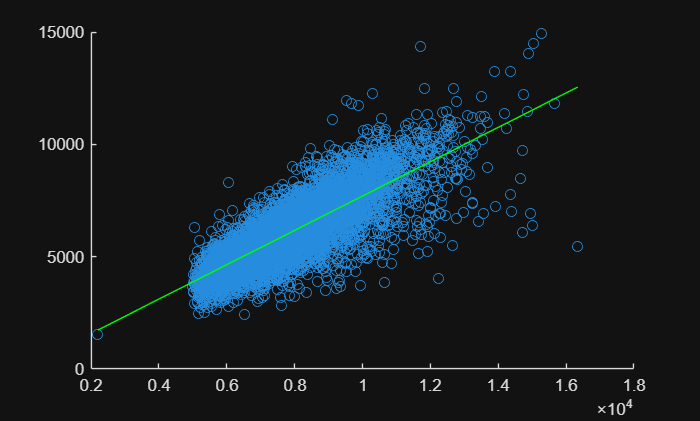

% scatter plot of population and trip origins
figure
hold on;    % fuck hold
scatter(data.Population, data.O_trips_)

% fitting a linear polynomial because why not?
p = polyfit(data.Population, data.O_trips_, 1);
pred = polyval(p, data.Population);

plot(data.Population, pred, Color='g')

hold off;


% performing linear regrssion to determine quantatitive relationship
mdl = fitlm(data.Population, data.O_trips_)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue 
                   ________    _________    ______    _______

    (Intercept)     51.798        50.503    1.0256    0.30509
    x1             0.76463     0.0063527    120.36          0


Number of observations: 7201, Error degrees of freedom: 7199
Root Mean Squared Error: 862
R-squared: 0.668,  Adjusted R-Squared: 0.668
F-statistic vs. constant model: 1.45e+04, p-value = 0

nrmse = mdl.RMSE/mean(data.O_trips_)

nrmse = 0.1436

Population describes 66.8% of overall Origin trip counts variance for the data, with an RMSE error of 862 and a normalised RMSE of 14.36%

b/c)

Testing correlation between trip origins and other features

% creating new table with predictors to be investigated
dataReduced = data(:, {'Population', 'Area', 'Households', 'TownsendDeprivationScore', 'O_trips_', 'D_trips_'})

dataReduced = 7201×6 table
    Population    Area    Households    TownsendDeprivationScore    O_trips_     D_trips_ 
    __________    ____    __________    ________________________    ________    __________

       7375       290        4385                3.9315               7580      7.1305e+05
       6775       216        2713                4.3451               3938            1248
      10045       214        3834                2.4328               7386            5604
       6182       249        2318               0.92629               4710            2030
       8562       119        3183                3.3548               5810            1736
       8791       174        3441                5.3836               5404            6126
      11569       142        4591                4.6399               7376            3018
       8395        96        3212                4.5456               5562             930
       8615       112        3292                4.7802       


mdl = fitlm(dataReduced, 'O_trips_')

mdl = Linear regression model:
    O_trips_ ~ 1 + Population + Area + Households + TownsendDeprivationScore + D_trips_

Estimated Coefficients:
                                Estimate        SE         tStat       pValue   
                                _________    _________    _______    ___________

    (Intercept)                   -370.23       44.552    -8.3102     1.1317e-16
    Population                    0.49453     0.011302     43.756              0
    Area                         -0.05259     0.001708    -30.791    1.1142e-195
    Households                     0.8001     0.026551     30.134    5.6308e-188
    TownsendDeprivationScore      -106.12       2.9492    -35.983    7.0795e-261
    D_trips_                    0.0049262    0.0007037     7.0005     2.7809e-12


Number of observations: 7201, Error degrees of freedom: 7195
Root Mean Squared Error: 731
R-squared: 0.761,  Adjusted R-Squared: 0.761
F-statistic vs. constant model: 4.59e+03, p-value = 0

nrmse = mdl.RMSE/mean(data.O_trips_)

nrmse = 0.1218

When population, area, household count, deprivation, and destination trip counts are considered only 76.1% of variance is explained, with a NRMSE of 12.18%, better than before but there is still a large amount of variance unexplained. There may be non-linear relations between some variables or other hidden third variables.

d)

aggregating origin and destination data *somehow*

Using MSOA codes to group location into towns/cities by name

dataReduced = data(:, {'MSOAName', 'O_trips_', 'D_trips_'})

dataReduced = 7201×3 table
              MSOAName               O_trips_     D_trips_ 
    _____________________________    ________    __________

    {'City of London 001E'      }      7580      7.1305e+05
    {'Barking and Dagenham 001A'}      3938            1248
    {'Barking and Dagenham 002F'}      7386            5604
    {'Barking and Dagenham 003A'}      4710            2030
    {'Barking and Dagenham 004A'}      5810            1736
    {'Barking and Dagenham 006C'}      5404            6126
    {'Barking and Dagenham 007A'}      7376            3018
    {'Barking and Dagenham 008C'}      5562             930
    {'Barking and Dagenham 009B'}      5586            1754
    {'Barking and Dagenham 010A'}      4406            4460
    {'Barking and Dagenham 011D'}      6676            1996
    {'Barking and Dagenham 012C'}      5360            1316
    {'Barking and Dagenham 013A'}      6100            2198
    {'Barking and Dagenham 014D'}      4654            1570
    {'Barkin


% removing the area code from MSOA names to keep only the town name
dataReduced{:, 'MSOAName'} = extractBefore(dataReduced{:, 'MSOAName'}, strlength(dataReduced{:, 'MSOAName'})-3);

% https://uk.mathworks.com/matlabcentral/answers/355643-grouping-elements-from-a-table
[group, id] = findgroups(dataReduced.MSOAName);
func = @(p, q) [sum(p), sum(q)];
result = splitapply(func, dataReduced.O_trips_, dataReduced.D_trips_, group);

dataGrouped = array2table([array2table(id), array2table(result)], 'VariableNames', dataReduced.Properties.VariableNames)

dataGrouped = 348×3 table
                MSOAName                  O_trips_      D_trips_ 
    _________________________________    __________    __________

                   id                     result1       result2  
    _________________________________    __________    __________
                                                                 
    {'Adur '                        }         46852         32640
    {'Allerdale '                   }         74338         63744
    {'Amber Valley '                }         98936         90568
    {'Arun '                        }    1.0526e+05         68832
    {'Ashfield '                    }         94418         90250
    {'Ashford '                     }         90034         84532
    {'Aylesbury Vale '              }    1.4172e+05    1.1142e+05
    {'Babergh '                     }         65658         52810
    {'Barking and Dagenham '        }    1.2047e+05         87278
    {'Barnet '                      }    2.6072e+